clc;
clear;
close all;

## Path and Single Data Structure Creation

actualPath = pwd;
savePath = fullfile(actualPath, 'Signal');
x = what(savePath);
x = x.mat;
length(x)

#### Plot the Given Signals

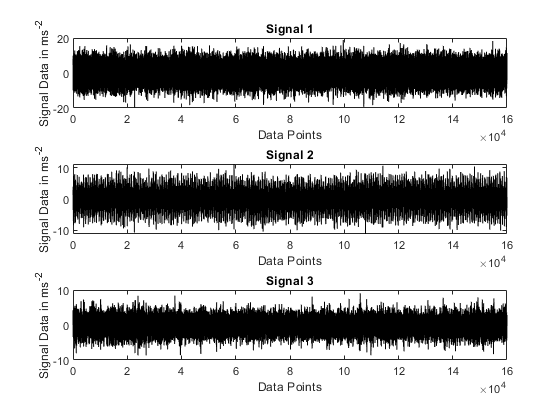

figure
for ii = 1:length(x)
    load(fullfile(savePath,x{ii,1}));
    subplot(3,1,ii)
    plot(data.datensatz(:,1),'k')
    title(['Signal ',num2str(ii)])
    xlim([0 16*10^4])
    xlabel('Data Points')
    ylabel('Signal Data in ms^{-2}')
    %     yline(M.mean_m(ii,1),'g')
    %     yline(M.rms_m(ii,1),'r')
    %     legend('signal','Mean','RMS')
end

## Time Domain Analysis

### Loading and Extracting Machine Features

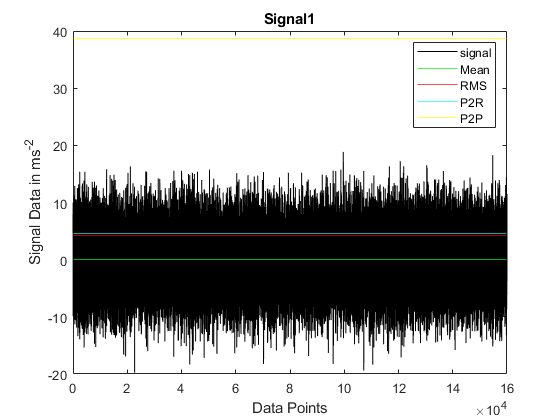

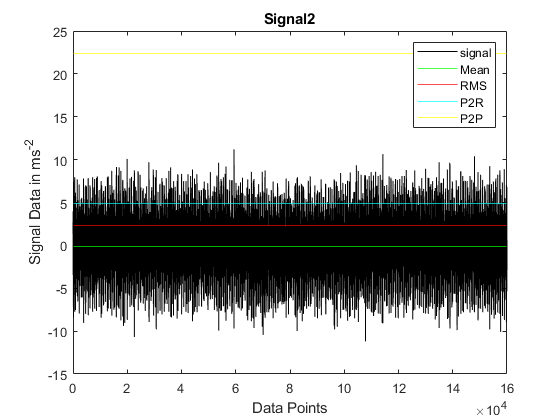

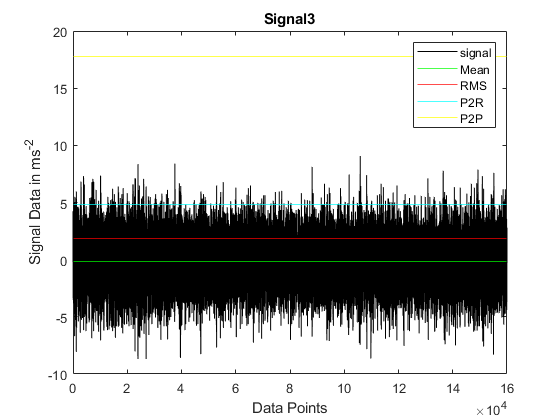

tic  % Stopwatch Timer to know the speed

rawdata = cell(1,3);
fre = zeros();

newLoad = 1;
if newLoad == 1
    for ii = 1:length(x)
        
        load(fullfile(savePath,x{ii,1}));
        
        rawdata{ii} = data.datensatz(:,1);
        
        fre(ii) = data.fn;
        
        M.var_m(ii,1) = var(data.datensatz(:,1));
        
        M.rms_m(ii,1) = rms(data.datensatz(:,1));
        
        M.mean_m(ii,1) = mean(data.datensatz(:,1));
        
        M.kurt_m(ii,1) = kurtosis(data.datensatz(:,1));
        
        M.p2r_m(ii,1) = peak2rms(data.datensatz(:,1));
        
        M.p2p_m(ii,1) = peak2peak(data.datensatz(:,1));
        
        M.quant_m(ii,1) = quantile(data.datensatz(:,1),0.5);
        
        figure
        plot(data.datensatz(:,1),'k')
        title(['Signal',num2str(ii)])
        xlim([0 16*10^4])
        xlabel('Data Points')
        ylabel('Signal Data in ms^{-2}')
        yline(M.mean_m(ii,1),'g')
        yline(M.rms_m(ii,1),'r')
        yline(M.p2r_m(ii,1),'c')
        yline(M.p2p_m(ii,1),'y')
        legend('signal','Mean','RMS','P2R','P2P')
        
    end
    
    save machinefeatures M
    
elseif newLoad == 0
    
    load machinefeatures
    
end

toc

Elapsed time is 8.756047 seconds.


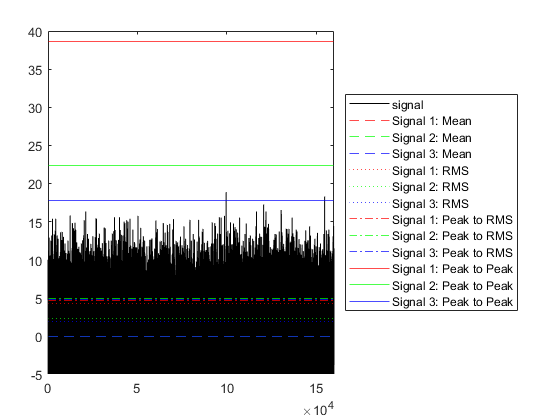


plot(rawdata{1},'k')

yline(M.mean_m(1,1),'r--')
yline(M.mean_m(2,1),'g--')
yline(M.mean_m(3,1),'b--')

yline(M.rms_m(1,1),'r:')
yline(M.rms_m(2,1),'g:')
yline(M.rms_m(3,1),'b:')

yline(M.p2r_m(1,1),'r-.')
yline(M.p2r_m(2,1),'g-.')
yline(M.p2r_m(3,1),'b-.')

yline(M.p2p_m(1,1),'r')
yline(M.p2p_m(2,1),'g')
yline(M.p2p_m(3,1),'b')

legend('signal','Signal 1: Mean','Signal 2: Mean','Signal 3: Mean','Signal 1: RMS','Signal 2: RMS','Signal 3: RMS','Signal 1: Peak to RMS','Signal 2: Peak to RMS','Signal 3: Peak to RMS','Signal 1: Peak to Peak','Signal 2: Peak to Peak','Signal 3: Peak to Peak','Location',"eastoutside")
axis([0 16*10^4 -5 40])

### Finding Relation Between The Signlas

#### Data Points

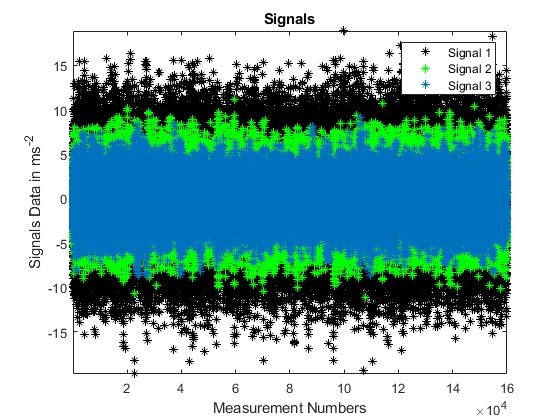


plot(rawdata{1},'*k')
hold on
% figure
plot(rawdata{2},'*g')
% figure
plot(rawdata{3},'*')
axis tight
hold off
xlabel('Measurement Numbers')
ylabel('Signals Data in ms^{-2}')
title('Signals')
legend('Signal 1','Signal 2','Signal 3')

#### Correlation

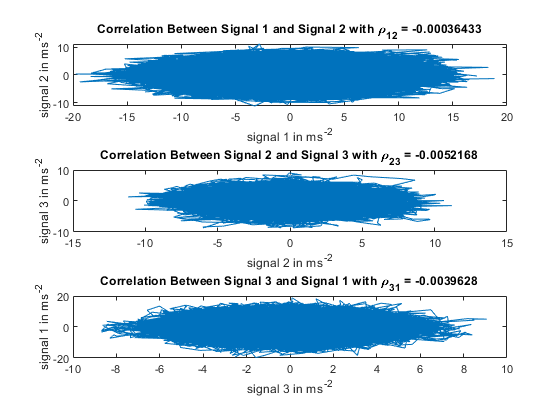


rhoSig12 = corrcoef(rawdata{1},rawdata{2});
rhoSig23 = corrcoef(rawdata{2},rawdata{3});
rhoSig13 = corrcoef(rawdata{1},rawdata{3});

figure
subplot(3,1,1)
plot(rawdata{1},rawdata{2})
xlabel('signal 1 in ms^{-2}')
ylabel('signal 2 in ms^{-2}')
title(['Correlation Between Signal 1 and Signal 2 with \rho_{12} = ',num2str(rhoSig12(1,2))])

subplot(3,1,2)
plot(rawdata{2},rawdata{3})
xlabel('signal 2 in ms^{-2}')
ylabel('signal 3 in ms^{-2}')
title(['Correlation Between Signal 2 and Signal 3 with \rho_{23} = ',num2str(rhoSig23(1,2))])

subplot(3,1,3)
plot(rawdata{3},rawdata{1})
xlabel('signal 3 in ms^{-2}')
ylabel('signal 1 in ms^{-2}')
title(['Correlation Between Signal 3 and Signal 1 with \rho_{31} = ',num2str(rhoSig13(1,2))])

### Probability Distribution Function

#### Histogram

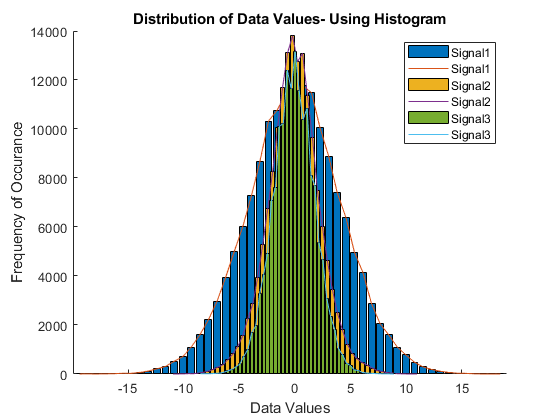

nclasses = 50;
 
figure
hold on
for ii = 1:length(x)
    
    [prob,center] = hist(rawdata{ii},nclasses);
    bar(center,prob, 'Displayname',['Signal' num2str(ii)])
    plot(center,prob,'Displayname',['Signal' num2str(ii)])
end
xlabel('Data Values')
ylabel('Frequency of Occurance')
title('Distribution of Data Values- Using Histogram')
legend toggle
hold off

#### Probability Density Using Matlab Function

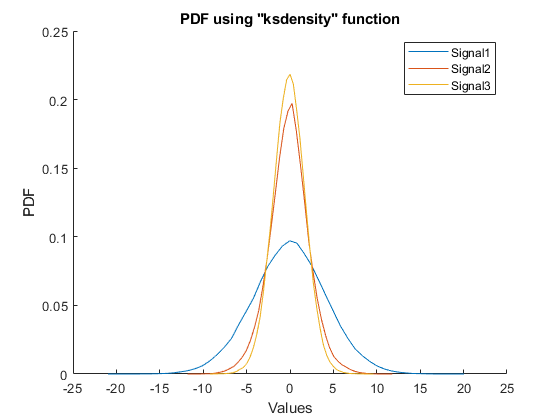

figure
hold on
for ii = 1 : length(x)
    [PDF,center1] = ksdensity(rawdata{ii},'npoints',nclasses);
%     bar(center1,PDF,'Displayname',['Signal' num2str(ii)])
    plot(center1,PDF,'Displayname',['Signal' num2str(ii)])
    xlabel('Values');
    ylabel('PDF');
    title('PDF using "ksdensity" function');
end
legend toggle
hold off

#### Probability Density by Manual Calculation

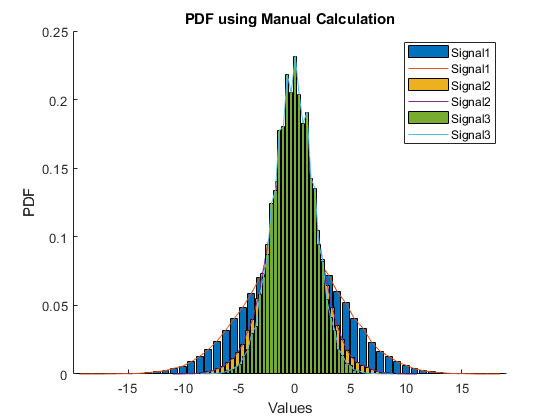

figure
hold on
for ii = 1:length(x)
    [prob,center] = hist(rawdata{ii},nclasses);
    probDens = prob ./ ((sum(prob)*(center(2)-center(1))));
    bar(center,probDens,'Displayname',['Signal' num2str(ii)]);
    plot(center,probDens,'Displayname',['Signal' num2str(ii)]);
    title('PDF using Manual Calculation');
    xlabel('Values');
    ylabel('PDF');
end
legend toggle
hold off

### Cumulative Distribution Function

#### CDF by Manual Calculation

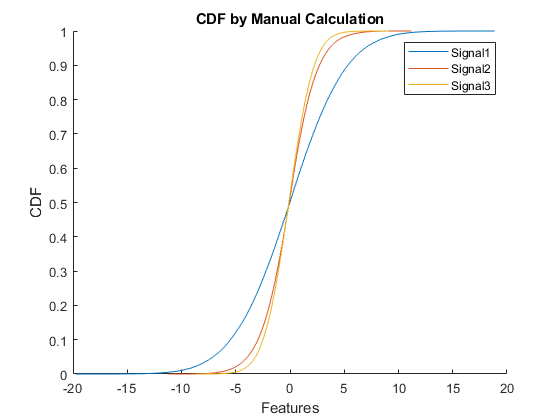

figure
hold on
for ii = 1:length(x)
    [dd,idx] = sort(rawdata{ii});
    X_ECDF = dd;
    Y_ECDF = (1/length(rawdata{ii})):(1/length(rawdata{ii})):1;
    plot(X_ECDF,Y_ECDF,'Displayname',['Signal' num2str(ii)]);
    xlabel('Features')
    ylabel('CDF')
    title('CDF by Manual Calculation')
end
legend toggle
hold off

#### CDF using Matlab Function

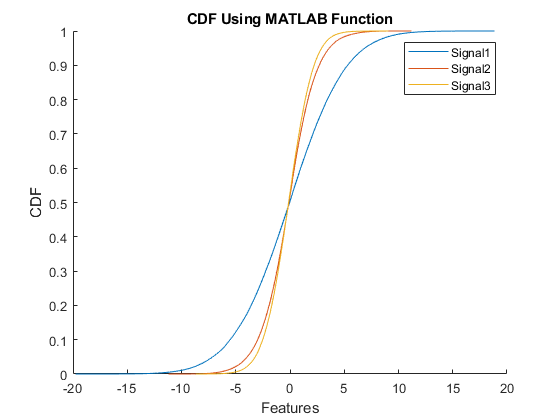

figure
hold on
for ii = 1:length(x)
    [fcdf, xcdf, flo, fup] = ecdf(rawdata{ii});
    plot(xcdf, fcdf,'Displayname',['Signal' num2str(ii)])
    xlabel('Features')
    ylabel('CDF')
    title('CDF Using MATLAB Function')
end
legend toggle
hold off

#### CDF by Integration of PDFs

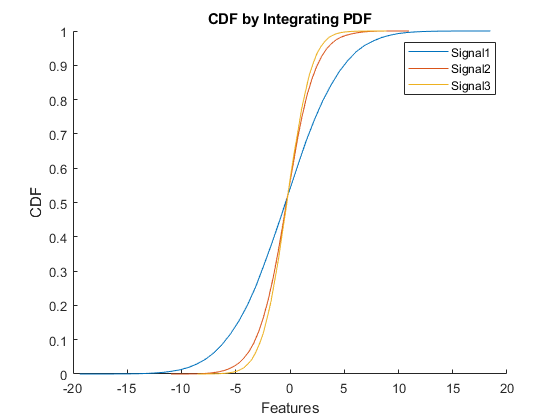

figure
hold on
for ii = 1:length(x)
    [prob,center]=hist(rawdata{ii},nclasses);
    probDens=prob/(sum(prob)*(center(2)-center(1)));
    
    X_IECDF = sort(center);
    Y_IECDF = cumsum(probDens./sum(probDens));
    plot(X_IECDF,Y_IECDF,'Displayname',['Signal' num2str(ii)])
    xlabel('Features')
    ylabel('CDF')
    title('CDF by Integrating PDF')
end
legend toggle
hold off

***From the above Time Domain Analysis, we can state the Signal 1 is the damaged one.***

***But to support this statement we are doing Frequency Domain Analysis in the following stages.***

## Frequency  Domain Analysis

### Power Spectrum Density 

#### Without Averaging and Number of Parts = 1

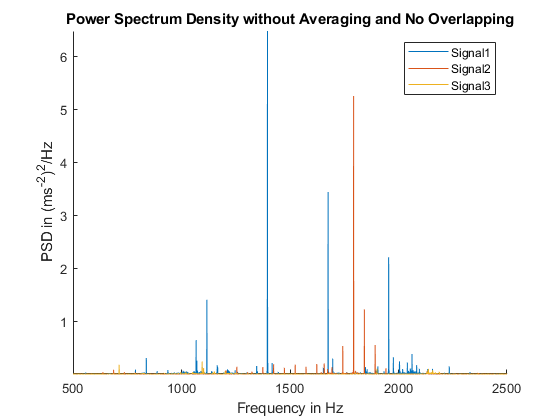

figure
% subplot(1,2,1)
hold on
for ii = 1:length(x)
    [s,f] = pwelch(rawdata{ii},window(@rectwin,length(rawdata{ii})),[],length(rawdata{ii}),data.fs);
    plot(f,s,'Displayname',['Signal' num2str(ii)]')
end
xlabel('Frequency in Hz')
ylabel('PSD in (ms^{-2})^{2}/Hz')
legend toggle
title('Power Spectrum Density without Averaging and No Overlapping')
hold off
axis tight
xlim([500 2500])

#### PSD in dB Scale

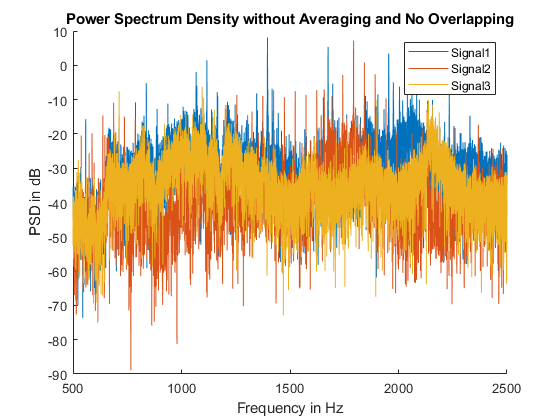

figure
% subplot(1,2,2)
hold on
for ii = 1:length(x)
    [s,f] = pwelch(rawdata{ii},window(@rectwin,length(rawdata{ii})),[],length(rawdata{ii}),data.fs);
    plot(f,10*log10(s),'Displayname',['Signal' num2str(ii)]')
    xlabel('Frequency in Hz')
    ylabel('PSD in dB')
end
xlabel('Frequency in Hz')
ylabel('PSD in dB')
legend toggle
title('Power Spectrum Density without Averaging and No Overlapping')
hold off
xlim([500 2500])

***Since we considered no overlapping the plots are not much useful for the analysis. Hence we take averaging of spectras with overlaping.***

#### ***PSD*** in dB Scale with Overlapping and Averaging of Spectras

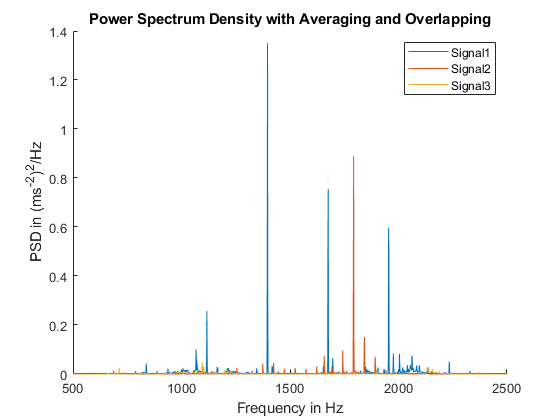

nfft = 2^15;
noverlap = nfft/2;
figure
hold on
for ii = 1:length(x)
    [s,f] = pwelch(rawdata{ii},window(@hann,nfft),noverlap,nfft,data.fs);
    plot(f,s,'Displayname',['Signal' num2str(ii)]')
%     plot(f,10*log10(s),'Displayname',['Signal' num2str(ii)]')
end
xlabel('Frequency in Hz')
% ylabel('PSD in dB')
ylabel('PSD in (ms^{-2})^{2}/Hz')
legend toggle
title('Power Spectrum Density with Averaging and Overlapping')
hold off
xlim([500 2500])

### Envelope Spectras

#### Envelope Signals and Hilbert Transformations

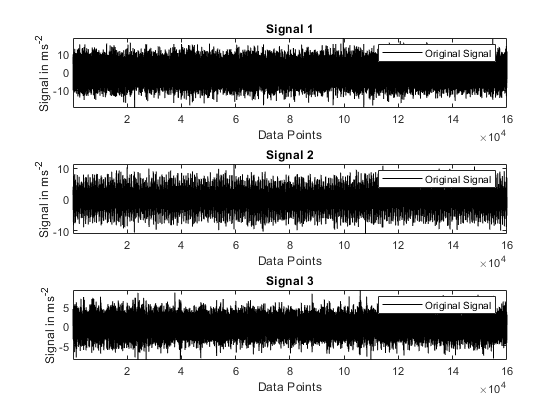

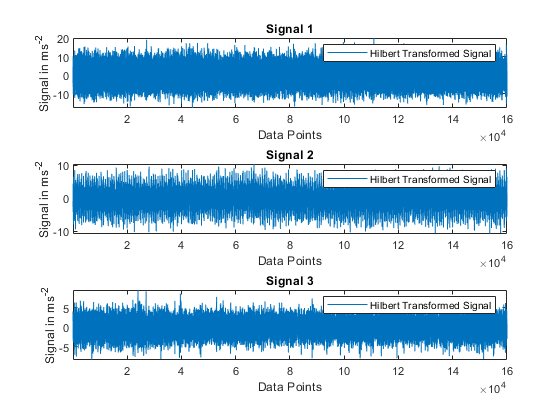

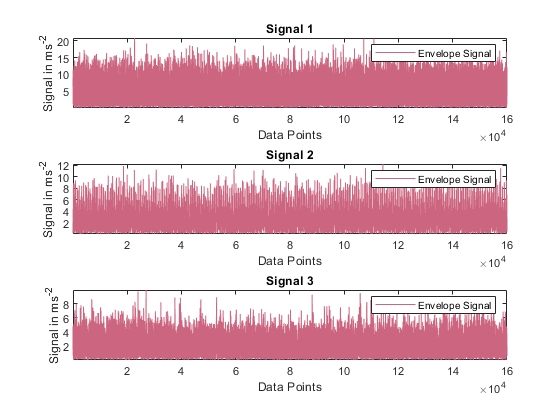


for ii = 1 : length(x)
    
    rawdata{ii} = rawdata{ii} - M.mean_m(ii);
    
    hilb = hilbert(rawdata{ii},length(rawdata{ii}));
    hImg = imag(hilb);
    
    h = sqrt(real(hilb).^2+imag(hilb).^2); % Evelope Curve using Hilbert Transformation as Output
    figure(1)
    subplot(3,1,ii)
    plot(real(hilb),'k')
    legend('Original Signal')
    axis tight
    xlabel('Data Points')
    ylabel('Signal in ms^{-2}')
    title(['Signal ',num2str(ii)])
    
    figure(2)
    subplot(3,1,ii)
    plot(imag(hilb))
    legend('Hilbert Transformed Signal')
    axis tight
    xlabel('Data Points')
    ylabel('Signal in ms^{-2}')
    title(['Signal ',num2str(ii)])
    
    figure(3)
    subplot(3,1,ii)
    plot(h,'color',[ 0.8 0.4 0.5])
    legend('Envelope Signal')
    axis tight
    xlabel('Data Points')
    ylabel('Signal in ms^{-2}')
    title(['Signal ',num2str(ii)])
        
end

#### Envelope Spectra Plots

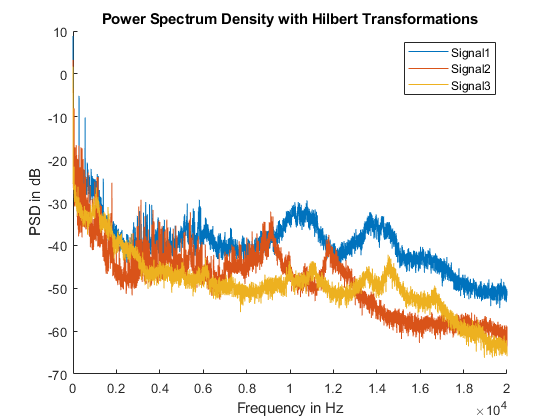

nfftH = 2^14;
noverlapH = nfftH/2;

figure
hold on

for ii = 1 : length(x)
    
    rawdata{ii} = rawdata{ii} - M.mean_m(ii);
    
    hilb = hilbert(rawdata{ii},length(rawdata{ii}));
    
    h = sqrt(real(hilb).^2 + imag(hilb).^2);
    
    [sH,fH] = pwelch(h,window(@hann,nfftH),noverlapH,nfftH,data.fs);
    
    plot(fH,10*log10(sH),'Displayname',['Signal' num2str(ii)]')
    
%     xlim([0 2000])
    
end

hold off
xlabel('Frequency in Hz')
ylabel('PSD in dB')
legend toggle
title('Power Spectrum Density with Hilbert Transformations')

### Type of Damage

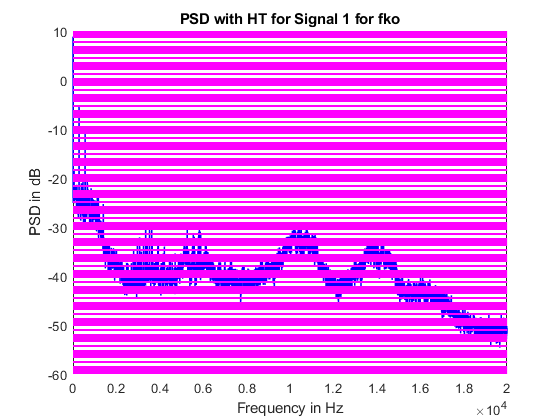

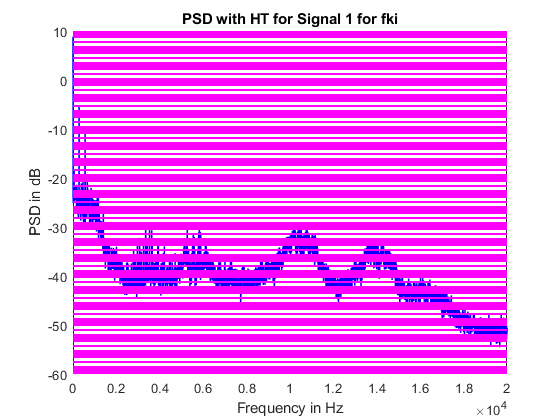

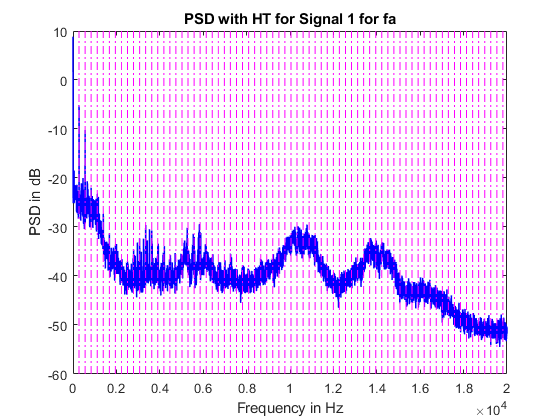

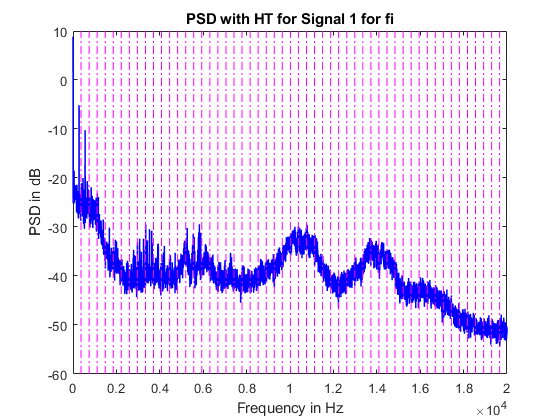

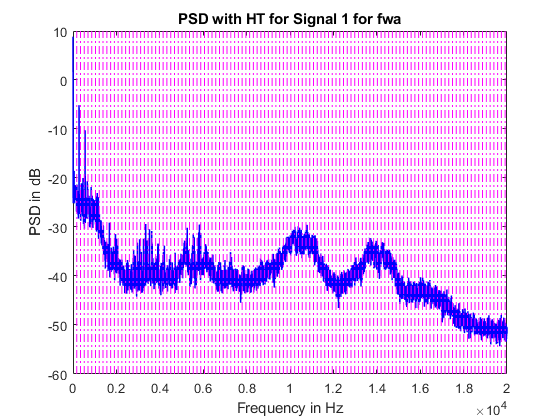

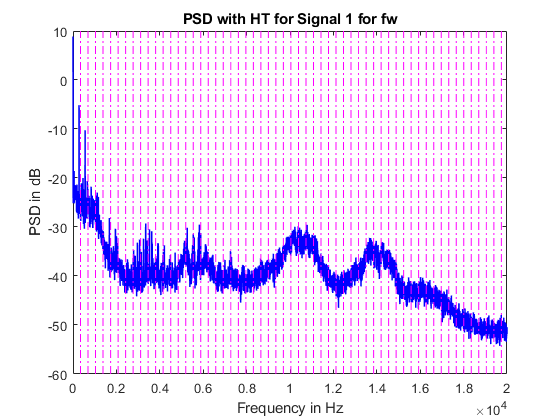

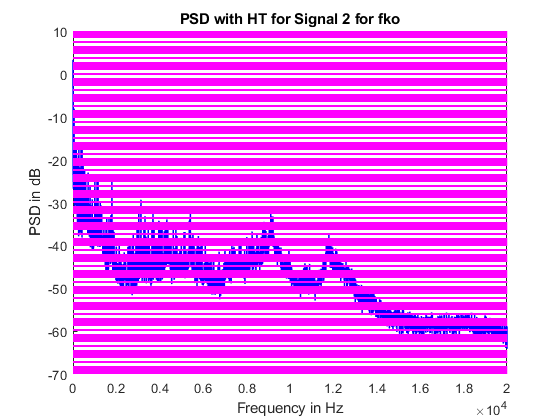

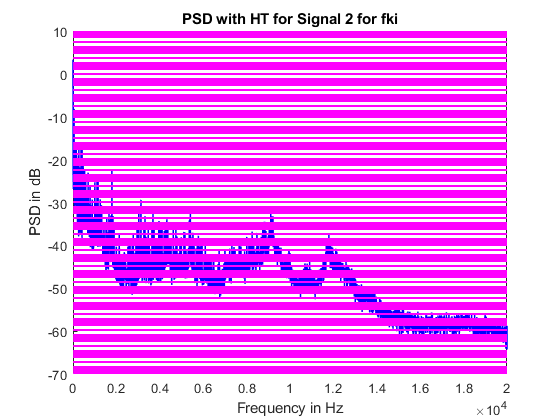

nfftH = 2^14;
noverlapH = nfftH/2;


nwk = 13;
Dw = 3.7; % Rolling Element Dia in mm
Dt = 26.15; % Part Cirlce Dia in mm
alpha = 0; % Contact Angle in degrees

fko = 0.5 * fre * (1-(Dw/Dt)*cos(alpha));

fki = 0.5 * fre * (1+(Dw/Dt)*cos(alpha));

fa = 0.5 * fre * nwk * (1-(Dw/Dt)*cos(alpha));

fi = 0.5 * fre * nwk * (1+(Dw/Dt)*cos(alpha));

fwa = 0.5 * fre * (Dt/Dw) * (1-((Dw/Dt)*cos(alpha))^2);

fw = 2 * fwa;

damaged_fre = [fko ; fki ; fa ; fi ; fwa ; fw];

damaged_fre_name = { 'fko' ; 'fki' ; 'fa' ; 'fi' ; 'fwa' ; 'fw' };

% damaged_fre_name = { 'Cage rotational frequency with fix outer ring (fko)' ; 
%                         'Cage rotational frequency with fix inner ring (fki)' ; 
%                             'Rollover frequency of an irregularity on the outer ring (fa)' ; 
%                                 'Rollover frequency of an irregularity on the inner ring (fi)' ; 
%                                     'Rolling element rotation frequency or rolling element spin frequency (fwa)' ; 
%                                         'Rollover frequency of a rolling element irregularity on both tracks (fw)' };

for ii = 1 : length(x)
    
    for jj = 1 : length(damaged_fre)
        
        figure
        
        rawdata{ii} = rawdata{ii} - M.mean_m(ii);
        
        hilb = hilbert(rawdata{ii},length(rawdata{ii}));
        
        h = sqrt(real(hilb).^2+imag(hilb).^2);
        
        [sH,fH] = pwelch(h,window(@hann,nfftH),noverlapH,nfftH,data.fs);
        
        plot(fH,10*log10(sH),'b','LineWidth',1,'Displayname',['Signal' num2str(ii)]')
        
        hold on
        
        spacing = damaged_fre(jj,ii) .* (1:1:(10 * length(fH)) / damaged_fre(jj,ii));
        
        plot(repmat(spacing,2,1),ylim,'-.m')
        
        hold off
        
        xlabel('Frequency in Hz')
        ylabel('PSD in dB')
        title(['PSD with HT for Signal ', num2str(ii),' for ', damaged_fre_name{jj}])   
        xlim([0 2*10^4])
        
    end
    
    
end